# Tutorial on signal modeling for lipid droplet size estimation using ALFONSO 

In this educational tutorial, we will develop from scratch a signal model definition file for the estimation of lipid droplet size from diffusion-weighted single-voxel magnetic resonance spectroscopy (MRS) based on spherically restricted diffusion.

Throughout this tutorial, we will discuss the following aspects: Brief introduction to ALFONSO's signal modeling conventions, (very brief) introduction of restricted diffusion modeling for droplet size estimation, required preparation steps including downloading and setting up ALFONSO, loading and inspection of the provided MRS data and the actual model definition and data fitting. 

Disclaimer: This tutorial is solely about model definition using ALFONSO and does not include any validation. 

## Theory

This section includes first a brief description on signal modeling using ALFONSO, and second a brief description of the Murday & Cotts model which will be used for the droplet size estimation. 

### Signal modeling in ALFONSO

ALFONSO signal models can generally be described as follows: 

The measured signal $S$ is defined as


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m$$


where $\Upsilon_m
$ is the free induction decay function 


$$\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{-\left( d_m + \frac{1}{2} g_m^2 t_n  \right) t_n} + \epsilon,$$


and $\Theta_m$ is the product of sequence specific modulator function, e.g.

$\Theta_m^{\text{TI}} = \left( 1 - 2 e^{- T_I T_{1,m}^{-1}} \right)$ for inversion recovery signal weighting or $\Theta_m^{\text{TE}} = e^{- T_E T_{2,m}^{-1}}$ for an echo time weighted signal. 

In ALFONSO a model $M\left( x \right)$is defined as $M\left( x \right) = S\left( \Psi\left( x \right) \right)$where a mapping function $\Psi$ is used to map the variable vector $x$  onto the signal $S$. 

The mapping function $\Psi$ is basically what is defined in the model definition file (plus e.g. optional model dimensions etc.) and therefore need to map the fitting vector $x$  on all used parameters of the signal $S$: 


$$\Psi\left( x \right)
\rightarrow
\left[\begin{array}{c}
        \rho\\
        \omega\\
        \phi\\
        d\\
        g\\
        T_1\\
        T_2\\
        D\\
        \vdots
\end{array}\right]
$$


For convenience, the first 6 dimension of $M\left( x \right)$are predefined as given below. All other dimensions can be freely defined in the model definition file. 


$$\begin{array}{llll}
\text{dimension} & \text{parameter} & \text{function} & \text{description} \\ 
1 & M & \text{species} & \text{separate species signals} \\  
2 & t & \Upsilon & \text{time domain signal} \\
3 & TI & \Theta^{\text{TI}} & \text{inversion recovery modulation} \\ 
4 & TE & \Theta^{\text{TE}} & \text{echo time modulation} \\
5 & TM & \Theta^{\text{TM}} & \text{mixing time modulation} \\
6 & b-value & \Theta^{\text{b-value}} & \text{diffusion weighting modulation} \\
\vdots & \vdots & \vdots & \text{free to define}
\end{array}$$


For additional information see also ALFONSO's Quickstart guide. 

### Droplet size estimation based on restricted diffusion effects

Very briefly: In the presence of diffusion weighting gradients, the observed signal of freely diffusing spins gets attenuated proportional to the applied b-value (diffusion weighting). In case for restricted diffusion, meaning spins are restricted by some barriers and cannot freely diffuse, the observed diffusion weighting is not only proportional to the b-value but also becomes time-dependent. 

Murday and Cotts (Ref. 1) described a solution for the case of spherically restricted diffusion and derived the following formula which will be used for the estimation of the radius of spherical lipid droplets: 


$$\ln \left(\frac{S_{\mathrm{MC}}(\Delta, \delta, G)}{S_0(\Delta)}\right)=-2 \gamma^{2} G^{2} \sum_{m=1}^{\infty}\left[\alpha_{m}^{2}\left(\alpha_{m}^{2}\left(\frac{d}{2}\right)^{2}-2\right)\right]^{-1} 
*\left(\frac{2 \delta}{\alpha_{m}^{2} D}-\frac{2+\exp \left(-\alpha_{m}^{2} D(\Delta-\delta)\right)-2 \exp \left(-\alpha_{m}^{2} D \delta\right)-2 \exp \left(-\alpha_{m}^{2} D \Delta\right)+\exp \left(-\alpha_{m}^{2} D(\Delta+\delta)\right)}{\left(\alpha_{m}^{2} D\right)^{2}}\right)$$


where $S_{\mathrm{MC}$ is the diffusion-weighted signal, $S_0$ is the relaxation-weighted spin density signal, ∆ is the diffusion time (DT), δ is the diffusion gradient length, $d$ is the spherical diameter of the restriction barrier, $D$ is the free diffusion constant, $G$ is the strength of the diffusion gradient, γ is the gyromagnetic moment, and $\alpha_m$are the roots of the following *Bessel* function:


$$$$
\left(\alpha_{m} \frac{d}{2}\right) J_{\frac{3}{2}}^{\prime}\left(\alpha_{m} \frac{d}{2}\right)-\frac{1}{2} J_{\frac{3}{2}}\left(\alpha_{m} \frac{d}{2}\right)=0
$$$$


For the provided dataset, which was acquired using a diffusion-weighted STEAM sequence, the relaxation-weighted spin density signal $S_0$ can be described as: 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m \Theta_{m}^{\mathrm{TM}} \Theta_{m}^{\mathrm{b-value}}$$


with$$$
\Theta_{m}^{\mathrm{TM}}=e^{-T_{M} T_{1, m}^{-1}}
$$$ and $$$
\Theta_{m}^{\mathrm{b-value}}=\mathrm{E}^{\mathrm{Murday\&Cotts}}
$$$where $$$
\mathrm{E}^{\mathrm{Murday\&Cotts}}
$$$is the weighting factor according to the formula by Murday and Cotts given above: 


$$\mathrm{E}^{\mathrm{Murday\&Cotts}}=\exp \left(-2 \gamma^{2} G^{2} \sum_{m=1}^{\infty}\left[\alpha_{m}^{2}\left(\alpha_{m}^{2}\left(\frac{d}{2}\right)^{2}-2\right)\right]^{-1} 
*\left(\frac{2 \delta}{\alpha_{m}^{2} D}-\frac{2+\exp \left(-\alpha_{m}^{2} D(\Delta-\delta)\right)-2 \exp \left(-\alpha_{m}^{2} D \delta\right)-2 \exp \left(-\alpha_{m}^{2} D \Delta\right)+\exp \left(-\alpha_{m}^{2} D(\Delta+\delta)\right)}{\left(\alpha_{m}^{2} D\right)^{2}}\right)\right)$$


This is also the final signal model we are aiming to define using ALFONSO. 

Further information about lipid droplet size estimation using diffusion-weighted STEAM MRS using clincial scanner hardware can also be found in the publication by Weidlich et al. (Ref. 2).

#### References

[1] J. S. Murday and R. M. Cotts, “Self-diffusion coefficient of liquid lithium,” *The Journal of Chemical Physics*, vol. 48, no. 11, pp. 4938–4945, Jan. 1968, doi: [10.1063/1.1668160](https://doi.org/10.1063/1.1668160).  

[2] D. Weidlich *et al.*, “Measuring large lipid droplet sizes by probing restricted lipid diffusion effects with diffusion-weighted MRS at 3T.,” *Magnetic Resonance in Medicine*, vol. 81, no. 6, pp. 3427–3439, Jun. 2019, doi: [10.1002/mrm.27651](https://doi.org/10.1002/mrm.27651).  

## Preparation 

Before we can get started, we need to download ALFONSO from github. This can be done from the terminal: 

In case the the git-lfs traffic traffic has exceeded, remaining files can be download from an alternative source from the terminal (assuming we are in the root directory of ALFONSO):  

Finally, add ALFONSO to the Matlab path (from the matlab console at ALFONSO's root directory): 

addALFONSO2path();

## Loading of provided data, inspection and preparation

In the following a preprocessed multi-b-value multi-TM diffusion-weighted STEAM MRS dataset which was acquired in a lipid droplet size phantom will be used. 

The dataset (given as ALFONSOobj file) can be read in as follows (assuming we are in the root directory of the tutorial): 

mrs = ALFONSO('ALFONSOobj_lipiddropletsize.mat');

Let's display some basic information about the dataset: 

mrs.data_info % display some information

Data information:
-------------------------------------------------------------------
Patient ID: XXXXXXXXXXXXXXXXXXXXXXXXXXXXXX
-------------------------------------------------------------------
Dimensions: x bvalue TM
Dimension size: 4096 4 6
TE (ms): 70
TM (ms): 200, 300, 400, 500, 600, 700
TR (ms): 1800
b-values (s/mm^2): 10000, 20000, 40000, 60000
DT (ms): 230, 330, 430, 530, 630, 730
Voxel size (mm^3): 15 x 15 x 15
Bandwidth (Hz): 5000 
Fieldstrength (T): 3 


As displayed here, the dataset is already preprocessed (and ready for our fitting job) and includes 4 b-values and 6 TMs. Additionally, also the diffusion time (DT) is given. 

More scan parameters can be found under *scanparam *where also the strength of the diffusion gradient $G$ (gr_str_magn_Tpm) and the diffusion gradient length δ (gr_dur_s) are given for example. 

mrs.scanparam

ans = struct with fields:
               filepathname: 'hidden'
                   filename: 'hidden'
                   metcycle: 0
                 patient_id: 'XXXXXXXXXXXXXXXXXXXXXXXXXXXXXX'
                  scan_name: 'WIP'
                  dynSeries: 'bvalue'
                 dynSeries2: 'TM'
              voxel_size_mm: [15 15 15]
               bandwidth_Hz: 5000
            fieldstrength_T: 3
                  gamma_bar: 4.2590e+07
      acq_window_center_ppm: 4.8254
                   n_sample: 4096
                   freqsign: -1
       precession_clockwise: 0
                      n_dyn: 4
                      n_mix: 1
                     n_coil: 8
                     n_echo: 1
                      n_loc: 1
                     n_aver: 16
                       TE_s: 0.0700
                       TM_s: [0.2000 0.3000 0.4000 0.5000 0.6000 0.7000]
                bvalue_spm2: [1.0000e+10 2.0000e+10 4.0000e+10 6.0000e+10]
                       TR_s: 1.8000
             

The spectra can also be visually inspected using the plot_dynSeries method: 

Recognized the following dyanmics: x, TM, bvalue


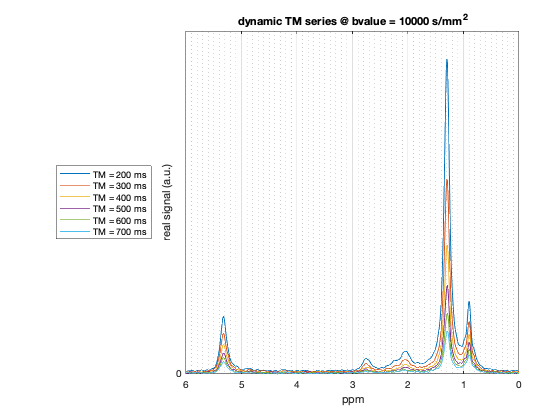

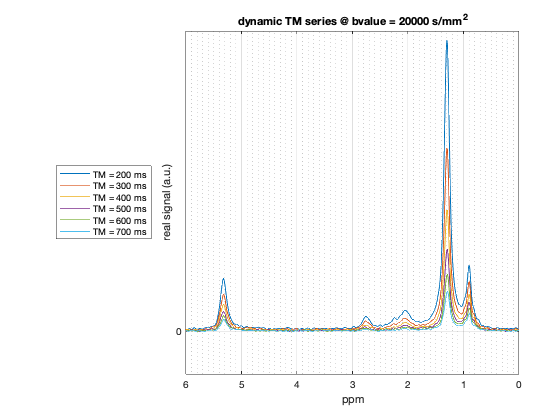

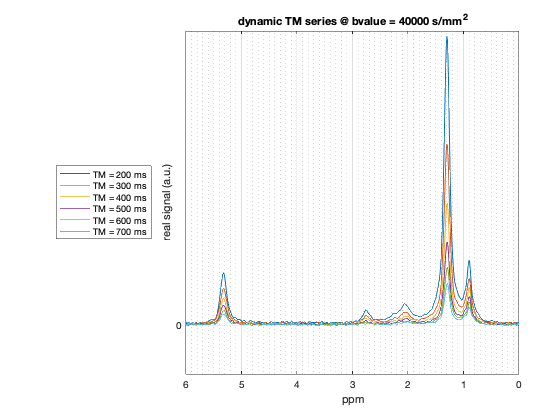

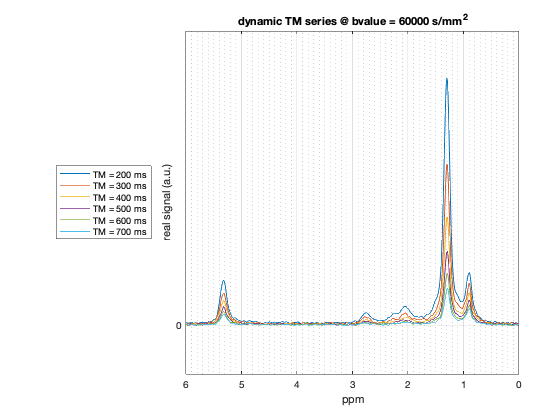

mrs.plot_dynSeries;

In the following, we will define a model to fit to the shown data. We will start from a very simple model and will then increase it's complexity and dimensionality. We will fist start with a dataset with a single spectrum without any dynamics and then add the b-value and TM dimensions one after another. 

Therefore, we will derive two additional datasets from our original dataset: *mrs_nodyn* which only contains a single spectrum and *mrs_bval* which only includes the b-value dimension. 

Recognized the following dyanmics: x, TE


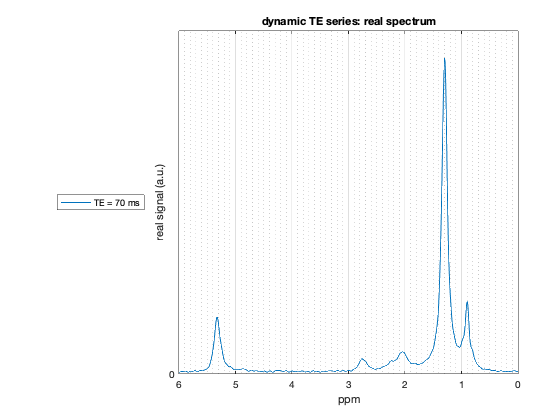

% dataset containing only a single spectrum and no dynamics
mrs_nodyn = copy(mrs);
mrs_nodyn.data = mrs_nodyn.data(:,1,1); % remove not needed data
mrs_nodyn.dims = {'x'}; % inform about reduced dimensionality 
mrs_nodyn.scanparam.bvalue_spm2 = mrs_nodyn.scanparam.bvalue_spm2(1); % inform about reduced dimensionality 
mrs_nodyn.scanparam.TM_s = mrs_nodyn.scanparam.TM_s(1); % inform about reduced dimensionality 
mrs_nodyn.scanparam.DT_s = mrs_nodyn.scanparam.DT_s(1); % inform about reduced dimensionality 
mrs_nodyn.squeeze_data_dim();
mrs_nodyn.plot_dynSeries();

Recognized the following dyanmics: x, bvalue


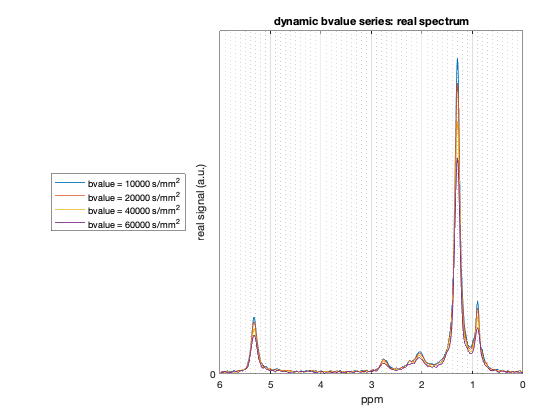

% dataset with removed TM dimension, only containing the b-value dimension
mrs_bval = copy(mrs);
mrs_bval.data = mrs_bval.data(:,:,1); % remove not needed data
mrs_bval.dims = {'x', 'bvalue'}; % inform about reduced dimensionality 
mrs_bval.scanparam.TM_s = mrs_bval.scanparam.TM_s(1); % inform about reduced dimensionality 
mrs_bval.scanparam.DT_s = mrs_bval.scanparam.DT_s(1); % inform about reduced dimensionality 
mrs_bval.squeeze_data_dim();
mrs_bval.plot_dynSeries();

Now we are done with the data preparation step and can now continue with defining our model. 

## Model definition

We will start with the *mrs_nodyn* dataset where we will try to fit the displayed fat spectrum: 

Recognized the following dyanmics: x, TE


mrs_nodyn.plot_dynSeries();

Let's start with fitting only a single species at 1.30 ppm. The corresponding model definition file then reads: 

type models/mrs_nodyn1.json


{
    "model_name": "mrs_nodyn1",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": 1,
    "rho_init": 1,
    "omega_ref": 1.3,
    "omega_vars": 2,
    "omega_init": 0,
    "d_vars": 3,
    "d_init": 0.1,
    "phi_vars": 4,
    "phi_init": 0
}


Let's briefly discuss the meaning of the given fields here: 

- model_name (string, required): name of the model

- description (string, optional): model description

- author (string, optional): model author

- created_date (string, optional): date of creation

- algorithm (string, optional): solver to be used. currently "levenberg-marquardt", "trust-region-reflective" and "NL2SOL". NL2SOL may require to compile the solver first. 

- rho_vars (variable mapping vector, required): mapping vector for $\varrho$. Here we map x(1) on $\varrho_1$ ( $\varrho$ of species 1)

- rho_init (array, required): initial value for $\varrho$ used by the solver. Spectra are normalized before fitting. 

- omega_ref (array, in ppm, required): reference frequency for all species in ppm. Here we set the reference frequency of $\varrho_1$ to 1.30 ppm

- omega_vars (variable mapping vector, required): mapping vector for $\omega$. Here we map x(2) on $\omega_1$ ( $\omega$  of species 1)

- omega_init (array, required): initial value for $\omega$ used by the solver. 

- d_vars (variable mapping vector, required): mapping vector for $d$ (*Lorentzian* damping factor). Here we map x(3) on $d_1$ ( $d$ of species 1)

- d_init (array, required): initial value for $d$ used by the solver. 

- phi_vars (variable mapping vector, required): mapping vector for $\phi$. Here we map x(4) on $\phi_1$ ( $\phi$ of species 1)

- phi_init (array, required): initial value for $\phi$ used by the solver. 

So in summary, this model will fit a single species at 1.30 ppm with a *Lorentzian* lineshape without any parameter constraints using the *Levenberg-Marquardt* solver. 

Effectively, the following signal model will be fitted: 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$. 

Let's read in the model, fit the model and visualize the result: 

Recognized the following dyanmics: x


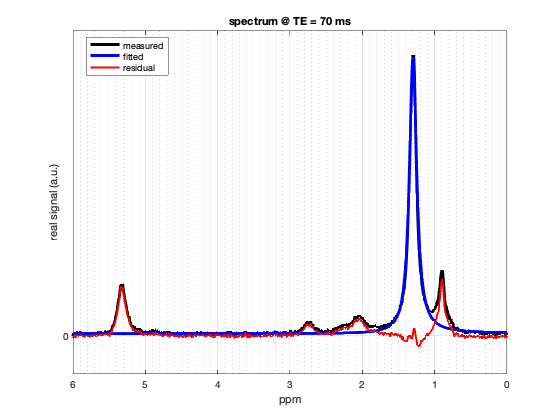

mrs_nodyn.set_model('models/mrs_nodyn1.json', 1)
mrs_nodyn.fit_model();
mrs_nodyn.plot_fit_model();

Here we can see that the methylene peak at 1.30 ppm was nicely fit (blue line), while all other peaks are not considered in the ftting. 

The fitted parameters can be accessed under

mrs_nodyn.quant{1}.output.param

ans = struct with fields:
      rho: 0.6878
    omega: 1.3003
        d: 7.6494
      phi: -0.0308


So at the moment we are only fitting a single species. Let's extend the model by fitting for all the triglyceride species. 

type models/mrs_nodyn2.json


{
    "model_name": "mrs_nodyn2",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "d_vars": 12,
    "d_init": 0.1,
    "phi_vars": 13,
    "phi_init": 0
}


The updated model now includes 10 species. Instead of 4 variables, the model contains now 13 variables including 9 more variables for fitting $\rho_{2...10}$. Since we did not add additional variables for $\omega$, $d$ and $\phi$, we constrained all species to have the same relative frequency offset ( $\omega$ ), *Lorentzian* damping factor ( $d$ ) and phase term ( $\phi$). 

Effectively, the following signal model (unchanged with respect to the model we fitted before) will be fitted: 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m $$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$.

Let's evaluate the updated model:

Recognized the following dyanmics: x


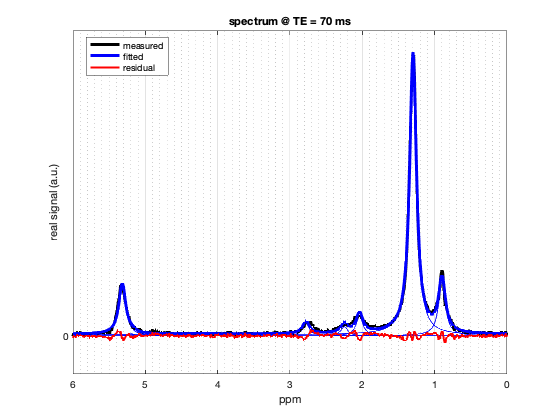

mrs_nodyn.set_model('models/mrs_nodyn2.json', 2)
mrs_nodyn.fit_model();
mrs_nodyn.plot_fit_model();

The updated model now better fits the spectral content. 

Let's have a look again at the fitted parameters: 

mrs_nodyn.quant{2}.output.param

ans = struct with fields:
      rho: [0.1271 0.6606 0.0018 0.0466 0.0219 0.0292 0.0015 0.0017 0.0049 0.1196]
    omega: [0.8985 1.2985 1.5885 2.0385 2.2485 2.7785 4.0985 4.2985 5.1885 5.3185]
        d: 7.2480
      phi: 0.0110


In a next step, we would like to increase the robustness of the model, by constraining $\varrho$ and $d$ to positive values; $\omega$ to [-0.2;0.2] ppm and $\phi$to [-0.2;0.2] rad. Since the *Levenberg-Marquardt solver *does not support upper and lower bounds, we will directly introduce the bounds in the model itself using a tanh()-based transformation for $\omega$ and $\phi$. 

ALFONSO already provides a bound_tanh() function which we will be using here: 

help ALFONSO.bound_tanh

 bound_tanh returns X using a tanh as bound function
    Xb = bound_tanh(X, LB, UB) bounds X between the lower bound LB and
    upper bound UB. 
 
  See also ALFONSO.bound_inv_tanh
 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
  Created:	Mar 20, 2020
 
  Revisions:    0.1 (Mar 20, 2020)
 					Initial version.
 
  Authors: 
 
    stefan.ruschke@tum.de
  
  --------------------------------
 
  Body Magnetic Resonance Research Group
  Department of Diagnostic and Interventional Radiology
  Technical University of Munich
  Klinikum rechts der Isar
  22 Ismaninger St., 81675 Munich
  
  https://www.bmrr.de
 
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



The updated model definition then reads as follows: 

type models/mrs_nodyn3.json


{
    "model_name": "mrs_nodyn3",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "d_vars": 12,
    "d_init": 0.1,
    "d_constraint": "@(x) exp(x(modelparam.d_vars))",
    "d_inv_constraint": "@(x) log(x(modelparam.d_vars))",
    "phi_vars": 13,
    "phi_init": 0,
    "phi_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.phi_vars), -0.2, 0.2)",
    "phi_inv_co

New fields named *{param}_constraint *and *{param}_inv_constraint *were added to the model for handling the constraints. * {param}_constraint  *describes the direct variable transformation. In the case of the $\varrho$ parameter, we defined a lambda function using the exponential function for the transformation. The used variable x is the variable vector which will be passed to this function and the helper variable modelparam allows to access the model parameter's variable indices during model evaluation. (rho_vars in this example for $\varrho$)

Effectively, the following signal model will be fitted (excluding constraints): 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$.

Recognized the following dyanmics: x


mrs_nodyn.set_model('models/mrs_nodyn3.json', 3)
mrs_nodyn.fit_model();
mrs_nodyn.plot_fit_model();

This time, we check if the fitted parameters are different between the two models (with vs. without constraints): 

mrs_nodyn.quant{3}.output.param.rho - mrs_nodyn.quant{2}.output.param.rho

ans = 	1.0e+-9 *

    0.5081   -0.1843    0.1280   -0.4519   -0.3705   -0.6455    0.3125    0.0303    0.1182   -0.3656


mrs_nodyn.quant{3}.output.param.omega - mrs_nodyn.quant{2}.output.param.omega

ans = 	1.0e+-9 *

   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102   -0.1102


mrs_nodyn.quant{3}.output.param.d - mrs_nodyn.quant{2}.output.param.d

ans = -4.3718e-09

mrs_nodyn.quant{3}.output.param.phi - mrs_nodyn.quant{2}.output.param.phi

ans = 1.8015e-09

So the differences are relatively small and both models can be considerd to yield equivalent results in this scenario. 

Let's continue by adding the b-value dimension which requires to add the diffusivity ( $D$ ) as an additional parameter: 

type models/mrs_bval1.json


{
    "model_name": "mrs_bval1",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "d_vars": 12,
    "d_init": 0.1,
    "d_constraint": "@(x) exp(x(modelparam.d_vars))",
    "d_inv_constraint": "@(x) log(x(modelparam.d_vars))",
    "phi_vars": 13,
    "phi_init": 0,
    "phi_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.phi_vars), -0.2, 0.2)",
    "phi_inv_con

Effectively, the following signal model will be fitted (excluding constraints): 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m  \Theta_{m}^{\mathrm{b-value}}$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$ and with$$$
\Theta_{m}^{\mathrm{b-value }}=e^{-b D_{m}}
$$$.

Again, performing the model fitting and displaying the result: 

Recognized the following dyanmics: x, bvalue


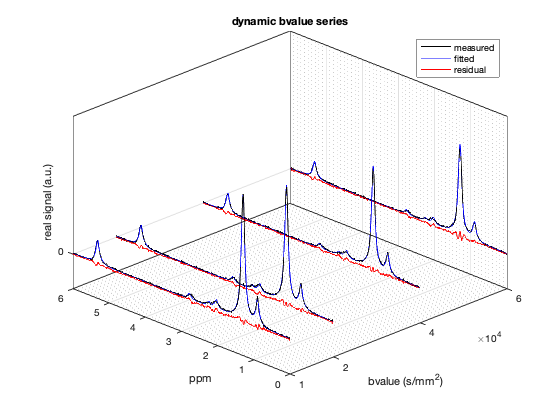

mrs_bval.set_model('models/mrs_bval1.json', 1)
mrs_bval.fit_model();
mrs_bval.plot_fit_model();

Here we see, that not only a single spectrum but a spectral series along the b-value dimension was fitted.

The fitted parameters are:

mrs_bval.quant{1}.output.param

ans = struct with fields:
      rho: [0.1361 0.7133 8.5398e-05 0.0498 0.0237 0.0317 0.0014 0.0020 0.0047 0.1292]
    omega: [0.8986 1.2986 1.5886 2.0386 2.2486 2.7786 4.0986 4.2986 5.1886 5.3186]
        d: 7.4319
      phi: 0.0146
        D: 6.4901e-12


Here, $D$ is given in SI units: m^2/sec

Let's continue with also bringing the TM dimension into consideration, which requires T1 as a model parameter. For robustness reasons we constrained T1 to be positive. 

type models/mrs1.json


{
    "model_name": "mrs1",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "d_vars": 12,
    "d_init": 0.1,
    "d_constraint": "@(x) exp(x(modelparam.d_vars))",
    "d_inv_constraint": "@(x) log(x(modelparam.d_vars))",
    "phi_vars": 13,
    "phi_init": 0,
    "phi_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.phi_vars), -0.2, 0.2)",
    "phi_inv_constrai

Effectively, the following signal model will be fitted (excluding constraints): 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m \Theta_{m}^{\mathrm{TM}} \Theta_{m}^{\mathrm{b-value}}$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$, $$$
\Theta_{m}^{\mathrm{TM}}=e^{-T_{M} T_{1, m}^{-1}}
$$$  and $$$
\Theta_{m}^{\mathrm{b-value }}=e^{-b D_{m}}
$$$.

Again, performing the fitting and visualization of results: 

Recognized the following dyanmics: x, TM, bvalue


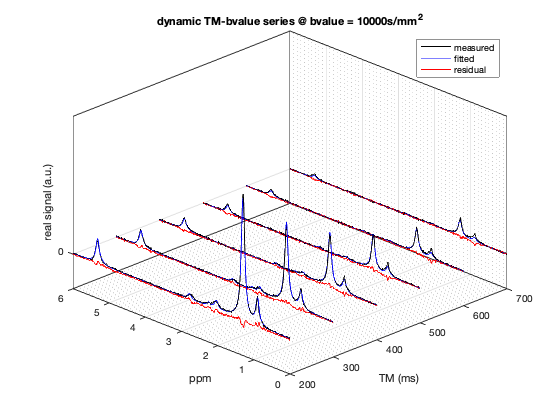

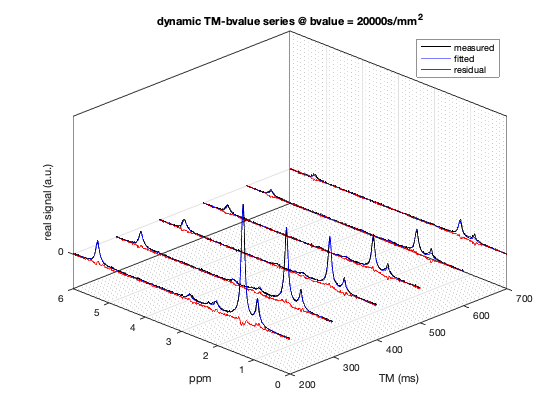

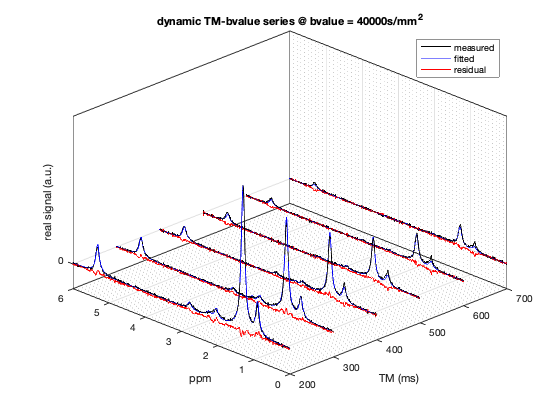

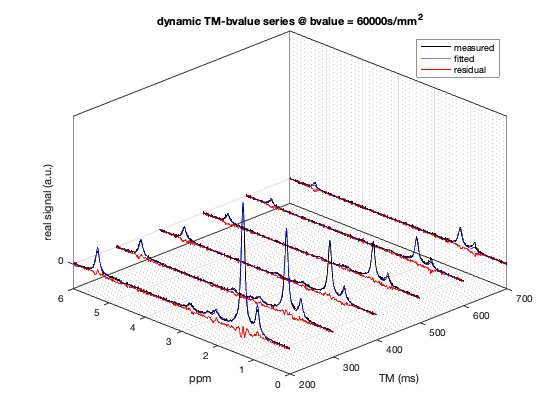

mrs.set_model('models/mrs1.json', 1)
mrs.fit_model();
mrs.plot_fit_model();

For visualization, we see now 4 plots with increasing b-value where each plot shows the variation along the TM dimension. 

The fitted parameters are: 

mrs.quant{1}.output.param

ans = struct with fields:
      rho: [0.3433 1.5648 0.0026 0.1089 0.0478 0.0717 0.0035 0.0047 0.0130 0.3093]
    omega: [0.8980 1.2980 1.5880 2.0380 2.2480 2.7780 4.0980 4.2980 5.1880 5.3180]
        d: 7.4410
      phi: 0.0110
       T1: 0.2447
        D: 6.2058e-12


In a next step we can allow T1 to vary freely across peaks and see how the squared 2-norm changes:

The corresponding model definition then reads: 

type models/mrs2.json


{
    "model_name": "mrs2",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "d_vars": 12,
    "d_init": 0.1,
    "d_constraint": "@(x) exp(x(modelparam.d_vars))",
    "d_inv_constraint": "@(x) log(x(modelparam.d_vars))",
    "phi_vars": 13,
    "phi_init": 0,
    "phi_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.phi_vars), -0.2, 0.2)",
    "phi_inv_constrai

Effectively, the following signal model will be fitted (excluding constraints): 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m \Theta_{m}^{\mathrm{TM}} \Theta_{m}^{\mathrm{b-value}}$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$, $$$
\Theta_{m}^{\mathrm{TM}}=e^{-T_{M} T_{1, m}^{-1}}
$$$  and $$$
\Theta_{m}^{\mathrm{b-value }}=e^{-b D_{m}}
$$$.

Recognized the following dyanmics: x, TM, bvalue


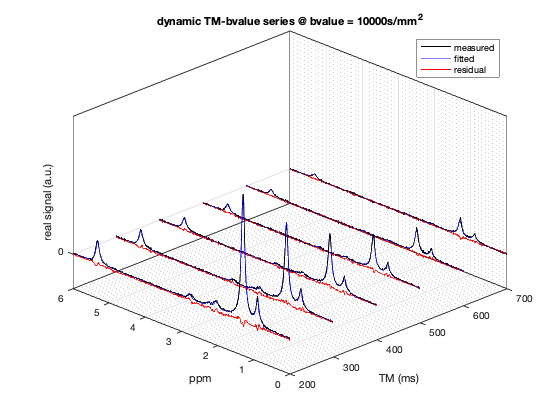

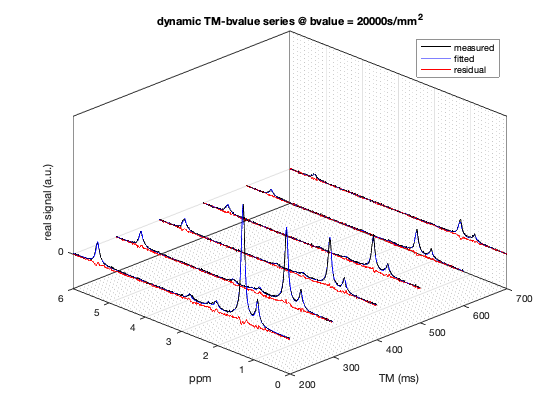

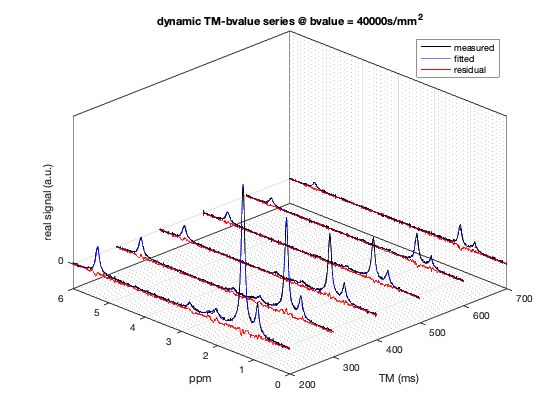

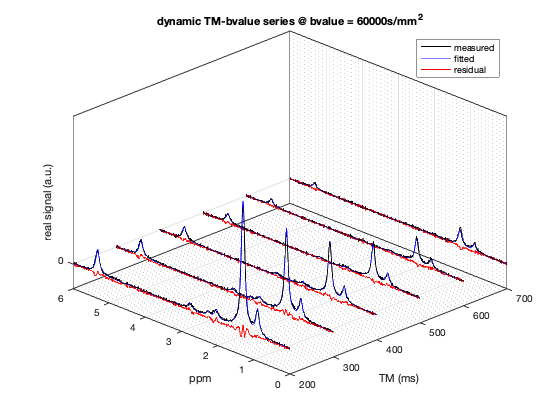

mrs.set_model('models/mrs2.json', 2)
mrs.fit_model();
mrs.plot_fit_model();

Fitting an individual T1 for each species yields:

mrs.quant{2}.output.param

ans = struct with fields:
      rho: [0.2166 1.6312 5.2175e+09 0.1152 0.0756 0.0731 0.0041 0.0051 0.0064 0.2418]
    omega: [0.8980 1.2980 1.5880 2.0380 2.2480 2.7780 4.0980 4.2980 5.1880 5.3180]
        d: 7.4431
      phi: 0.0110
       T1: [0.4046 0.2360 0.0070 0.2331 0.1719 0.2406 0.2134 0.2274 0.6130 0.3120]
        D: 6.2050e-12


disp(['Squared 2-norm ratio [T1 unconstrained] / [T1 constrained]: ' num2str(mrs.quant{2}.output.resnorm / mrs.quant{1}.output.resnorm)])

Squared 2-norm ratio [T1 unconstrained] / [T1 constrained]: 0.92656


Now as a final step, we want to directly fit the Murday & Cotts model to the data. In this example we will fit a common radius to all triglyceride species. 

Therefore, using the field *add_scan_param *we will inform the model about additional scan parameters which we will be using: 

- diffusion time DT

- diffusion gradient duration gr_dur_s

- diffusion gradient strength gr_str_magn_Tpm

- gyromagnetic ratio gamma_bar

Also a new model parameter is introduced using *add_model_param*: 

- radius $r$

And finally, the default Theta function for the b-value dimension will be overruled using the Murday & Cotts model: 

- bvalue_func = @(D,r) ALFONSO.model_murdaycotts(r(:),D(:),DT,gr_str_magn_Tpm,gr_dur_s,gamma_bar);

Here we are use the Murday&Cotts model function already provided by ALFONSO: 

help ALFONSO.model_murdaycotts 

 model_murdaycotts calculates the restricted diffusion modulation according
 to Murday and Cotts (see Ref. 3)
 
    mcw = model_murdaycotts( r, D, DT, G_str, G_dur, gamma_bar ) calculates
        the signal modulation (relative weighting factor) for restricted 
        diffusion effects according to Murday and Cotts (3). Therefore the 
        function M( 2*tau, delta, G) / M_0 as described in Eq. 4 from 
        Ref. 3 is calucalted excluding T2 relaxation.  
 
    Parameters:
    	- r: radius [m]
        - D: diffusion constant (temperature dep.) [m^2/sec]
        - DT: diffusion time [s]
        - G_str: gradient strength [T/m]
        - G_dur: gradient pulse duration [s]
        - gamma_bar: gamma_bar in [Hz/Tesla]
        - J0_roots: roots (optional)
 
    Returns:
        - mcw: normalized signal weighting factor [-]
 
  References:
        1. Wayne and Cotts, “Nuclear-Magnetic-Resonance Study of
            Self-Diffusion in a Bounded Medium,” P

The final model definition file: 

type models/mrs_mc.json


{
    "model_name": "mrs_mc",
    "description": "Model descpription goes here.",
    "author": "Stefan Ruschke (stefan.ruschke@tum.de)",
    "created_date": "May 01, 2022",
    "algorithm": "levenberg-marquardt",
    "rho_vars": [1, 2, 3, 4, 5, 6, 7, 8, 9, 10],
    "rho_init": 0.1,
    "rho_constraint": "@(x) exp(x(modelparam.rho_vars))",
    "rho_inv_constraint": "@(x) log(x(modelparam.rho_vars))",
    "omega_ref": [0.9, 1.3, 1.59, 2.04, 2.25, 2.78, 4.10, 4.30, 5.19, 5.32],
    "omega_vars": 11,
    "omega_init": 0,
    "omega_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "omega_inv_constraint": "@(x) ALFONSO.bound_inv_tanh(x(modelparam.omega_vars), -0.2, 0.2)",
    "d_vars": 12,
    "d_init": 0.1,
    "d_constraint": "@(x) exp(x(modelparam.d_vars))",
    "d_inv_constraint": "@(x) log(x(modelparam.d_vars))",
    "phi_vars": 13,
    "phi_init": 0,
    "phi_constraint": "@(x) ALFONSO.bound_tanh(x(modelparam.phi_vars), -0.2, 0.2)",
    "phi_inv_constr

Effectively, the following signal model will be fitted (excluding constraints): 


$$S = \sum_{m=1}^M \Upsilon_m \Theta_m = \sum_{m=1}^M \Upsilon_m \Theta_{m}^{\mathrm{TM}} \Theta_{m}^{\mathrm{b-value}}$$


with $\Upsilon\left(t_n\right) = \varrho_m e^{i 2 \pi \omega_m t_n} e^{i \phi_m}  e^{- d_m  t_n}$, $$$
\Theta_{m}^{\mathrm{TM}}=e^{-T_{M} T_{1, m}^{-1}}
$$$  and $$$
\Theta_{m}^{\mathrm{b-value}}=\mathrm{E}^{\mathrm{Murday\&Cotts}}
$$$ and


$$\mathrm{E}^{\mathrm{Murday\&Cotts}}=\exp \left(-2 \gamma^{2} G^{2} \sum_{m=1}^{\infty}\left[\alpha_{m}^{2}\left(\alpha_{m}^{2}\left(\frac{d}{2}\right)^{2}-2\right)\right]^{-1} 
*\left(\frac{2 \delta}{\alpha_{m}^{2} D}-\frac{2+\exp \left(-\alpha_{m}^{2} D(\Delta-\delta)\right)-2 \exp \left(-\alpha_{m}^{2} D \delta\right)-2 \exp \left(-\alpha_{m}^{2} D \Delta\right)+\exp \left(-\alpha_{m}^{2} D(\Delta+\delta)\right)}{\left(\alpha_{m}^{2} D\right)^{2}}\right)\right)$$


Evaluation of the final model: 

Recognized the following dyanmics: x, TM, bvalue


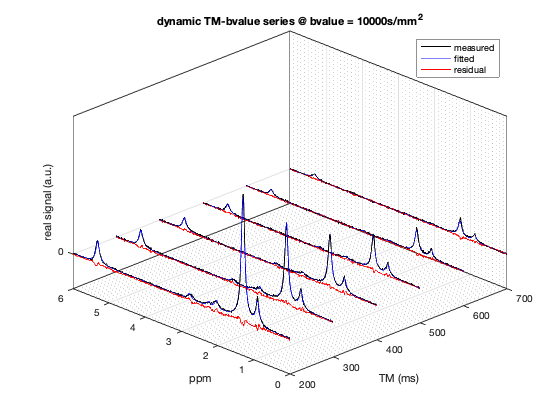

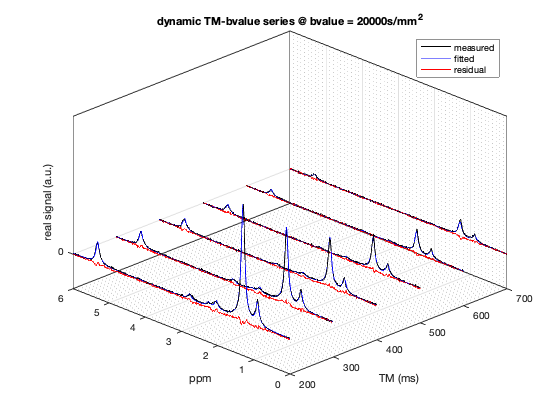

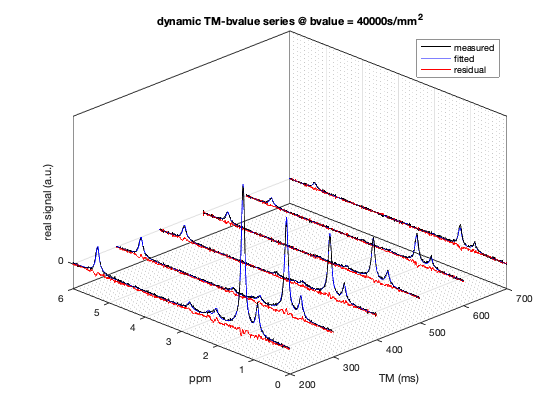

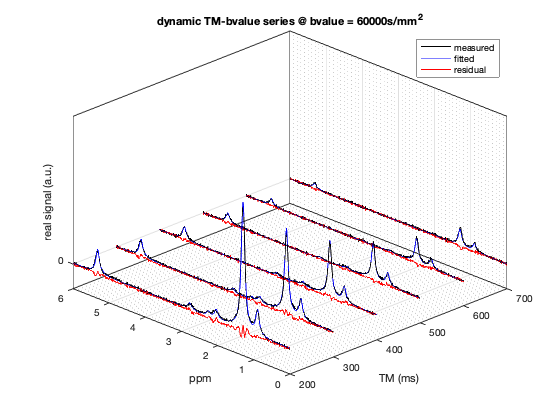

mrs.set_model('models/mrs_mc.json', 3)
mrs.fit_model();
mrs.plot_fit_model();

Inspecting the fitting results: 

mrs.quant{3}.output.param

ans = struct with fields:
      rho: [0.2198 1.6562 1.2595e+04 0.1169 0.0767 0.0742 0.0042 0.0052 0.0065 0.2454]
    omega: [0.8980 1.2980 1.5880 2.0380 2.2480 2.7780 4.0980 4.2980 5.1880 5.3180]
        d: 7.4429
      phi: 0.0110
       T1: [0.3960 0.2329 0.0129 0.2302 0.1703 0.2375 0.2109 0.2250 0.5924 0.3068]
        D: 3.0576e-10
        r: 4.6063e-05


disp(['Fitted radius: ' num2str(mrs.quant{3}.output.param.r .* 1e6) ' µm'])

Fitted radius: 46.0631 µm


This fitting result also concludes this tutorial. 

## Summary / recap

- We started with a brief introducing of the basic concepts of signal model definition using ALFONSO and droplet size estimation based on restricted diffusion using the Murday&Cotts signal model. 

- We loaded and inspected the provided multi-b-value multi-TM diffusion weighted STEAM dataset (*mrs*). Also, we extracted two sub-datasets containing a) only a single spectrum (*mrs_nodyn*) and b) only the multi-b-value dimension (*mrs_bval*). 

- We slowly build up our model starting with the single spectrum where we added multiple species and introduced constraints. 

- Then we added the b-value dimension using the *mrs_bval* dataset where we added the free diffusivity $D$ as additional parameter. 

- Then we started working on the full dataset which also included the TM / DT dimension. First, we added a common T1 for all species as additional parameter. Second, we unconstrained T1 and allowed different T1s for all species resulting in a better fit based on a smaller squared 2-norm. Finally, we informed our model about additional scan parameters and model parameters which could be used in the b-value Theta function which we overloaded with the Murday&Cotts signal model.

Feel free to reach out if you have any suggestions, comments or questions. 

Stefan Ruschke (*stefan.ruschke@tum.de*) & Dimitrios Karampinos (*dimitrios.karampinos@tum.de*)